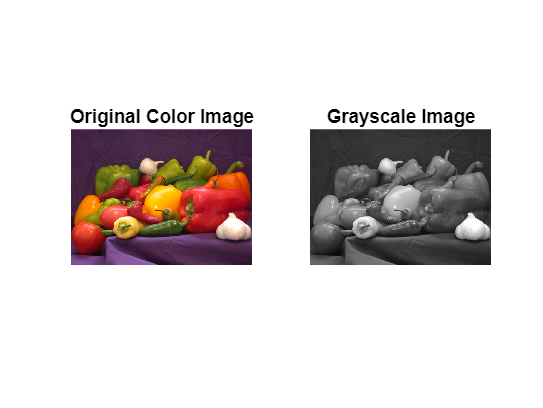


img = imread('peppers.png');


grayImg = rgb2gray(img);

figure;
subplot(1,2,1);
imshow(img);
title('Original Color Image');

subplot(1,2,2);
imshow(grayImg);
title('Grayscale Image');

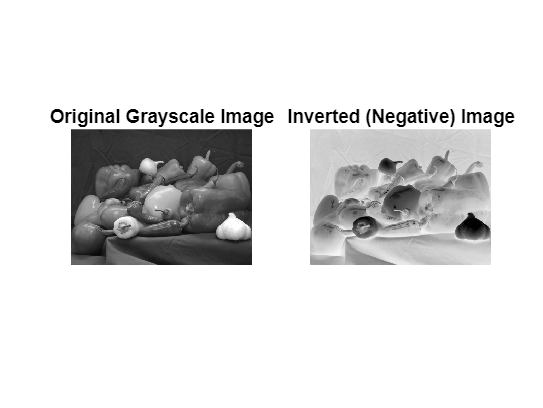




invertedImg = 255 - grayImg;

figure;
subplot(1,2,1);
imshow(grayImg);
title('Original Grayscale Image');

subplot(1,2,2);
imshow(invertedImg);
title('Inverted (Negative) Image');

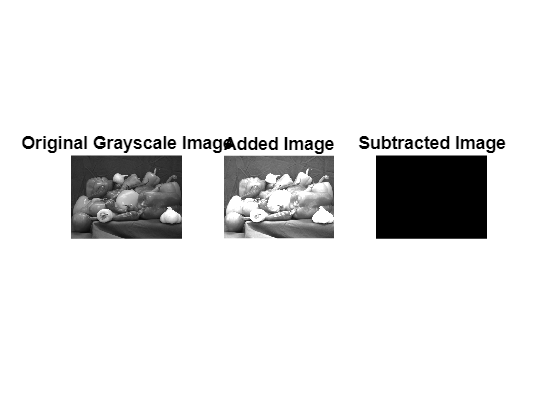




grayImg2 = imresize(rgb2gray(imread('peppers.png')), size(grayImg));

addedImg = imadd(grayImg, grayImg2);
subtractedImg = imsubtract(grayImg, grayImg2);

figure;
subplot(1,3,1);
imshow(grayImg);
title('Original Grayscale Image');

subplot(1,3,2);
imshow(addedImg);
title('Added Image');

subplot(1,3,3);
imshow(subtractedImg);
title('Subtracted Image');

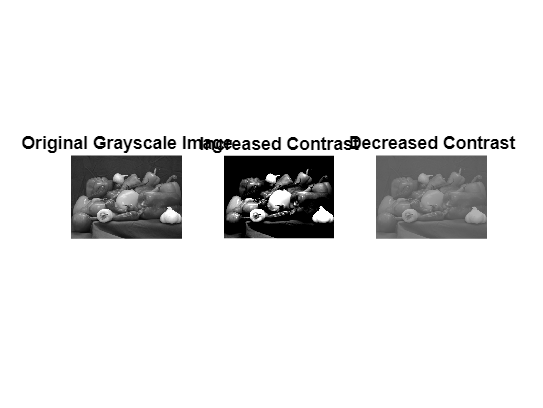



increasedContrast = imadjust(grayImg, [0.3 0.7], [0 1]);
decreasedContrast = imadjust(grayImg, [0 1], [0.3 0.7]);

figure;
subplot(1,3,1);
imshow(grayImg);
title('Original Grayscale Image');

subplot(1,3,2);
imshow(increasedContrast);
title('Increased Contrast');

subplot(1,3,3);
imshow(decreasedContrast);
title('Decreased Contrast');